## Problem 1)Basic Plant Response Analysis

### a)Open-Loop Analysis:

s=tf('s');
G=100/(s^2+15*s+50);

#### Plotting the Graph

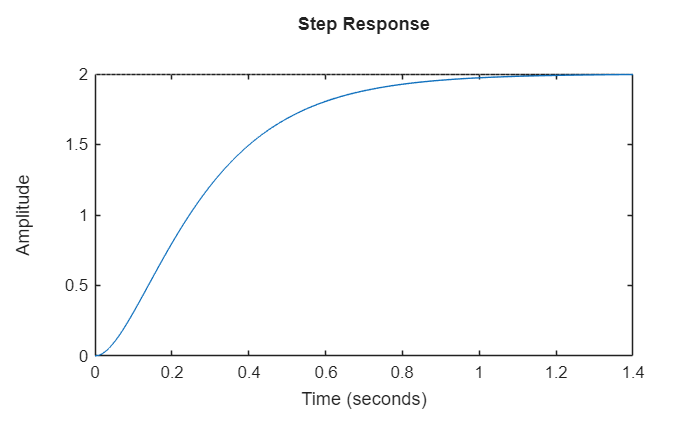

step(G)

stepinfo(G)

ans = struct with fields:
         RiseTime: 0.5180
    TransientTime: 0.9200
     SettlingTime: 0.9200
      SettlingMin: 1.8045
      SettlingMax: 1.9983
        Overshoot: 0
       Undershoot: 0
             Peak: 1.9983
         PeakTime: 1.5565


### b)P controller design

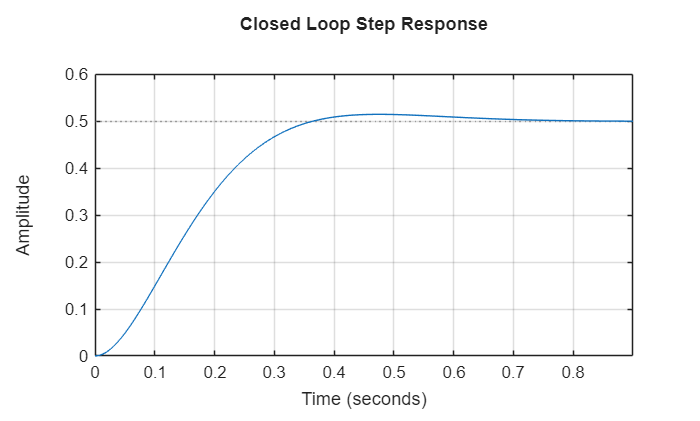

Kp=0.5;
C=Kp;
T=feedback(C*G,1);
step(T)
grid on
title('Closed Loop Step Response')

stepinfo(T)

ans = struct with fields:
         RiseTime: 0.2288
    TransientTime: 0.5743
     SettlingTime: 0.5743
      SettlingMin: 0.4524
      SettlingMax: 0.5142
        Overshoot: 2.8369
       Undershoot: 0
             Peak: 0.5142
         PeakTime: 0.4728


1)The given system is a TYPE 0 system

2)The steady-state error for a TYPE 0 system for a step input is non-zero

3)Increase in Kp can reduce the error but not eliminate it.

4)Integrator is required to make the Sterady state error 0.

### c)PI controller Design

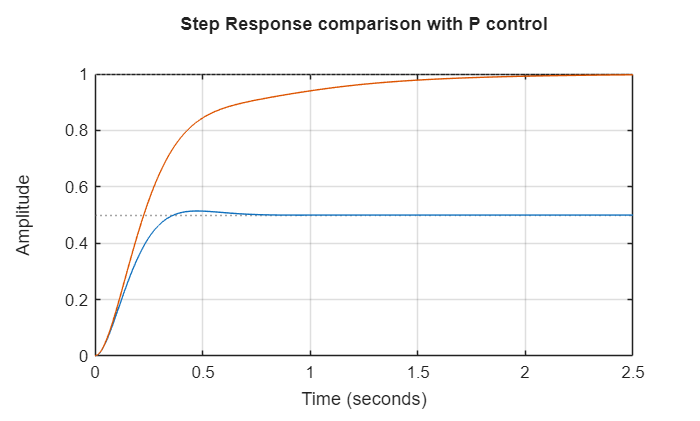

Ki=1.5;
C_PI=Kp+Ki/s;
T_PI=feedback(C_PI*G,1);
C_P=Kp;
T_P=feedback(C_P*G,1);
step(T_P,T_PI)
grid on
title('Step Response comparison with P control')

stepinfo(T_PI)

ans = struct with fields:
         RiseTime: 0.6278
    TransientTime: 1.5377
     SettlingTime: 1.5377
      SettlingMin: 0.9016
      SettlingMax: 0.9981
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9981
         PeakTime: 2.6861


- Integral action increases the system type from TYPE 0 to TYPE 1.

- For a TYPE 1 system,the steady-state error for a step input is zero.

- The integrator accumulates error overtime and drives it to 0.

### d)PID controller Tuning

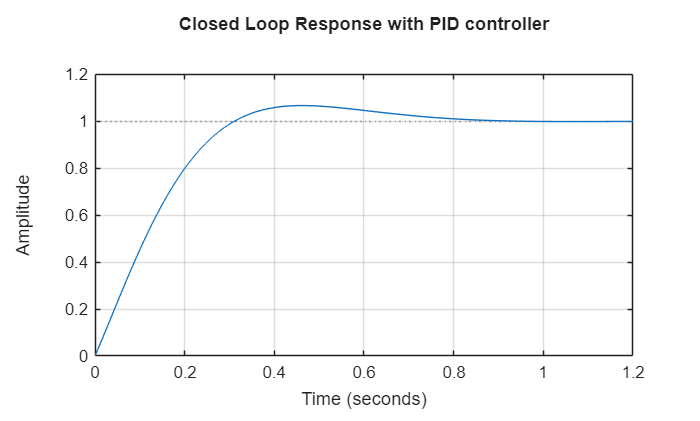

C_PID=pidtune(G,'PID');
Kp=C_PID.Kp;
Ki=C_PID.Ki;
Kd=C_PID.Kd;
T_PID=feedback(C_PID*G,1);
step(T_PID)
grid on
title('Closed Loop Response with PID controller')

stepinfo(T_PID)

ans = struct with fields:
         RiseTime: 0.2225
    TransientTime: 0.7237
     SettlingTime: 0.7237
      SettlingMin: 0.9053
      SettlingMax: 1.0657
        Overshoot: 6.5696
       Undershoot: 0
             Peak: 1.0657
         PeakTime: 0.4604


C_PID


C_PID =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.993, Ki = 4.84, Kd = 0.0442
 
Continuous-time PID controller in parallel form.


## Problem 2)Complex Input Tracking

### a)Multi-Step Reference:

#### Create multi-step Reference:

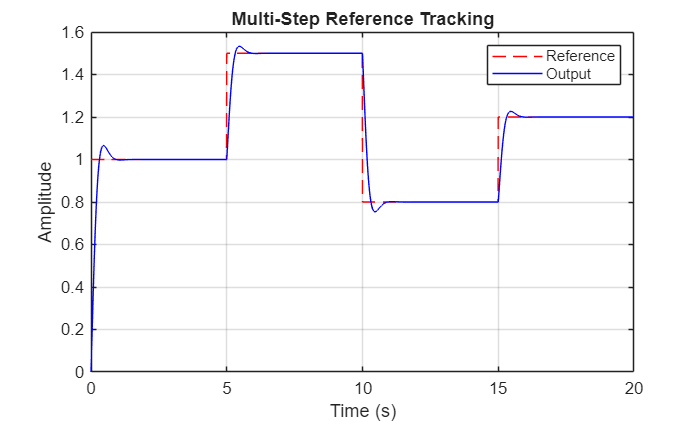

t=0:0.01:20;
r=zeros(size(t));
for i=1:length(t)
    if t(i)<5
        r(i)=1;
    elseif t(i)<10
        r(i)=1.5;
    elseif t(i)<15
        r(i)=0.8; 
    else
        r(i)=1.2;
    end
end    
%Simulate using lsim():
[y,t_out]=lsim(T_PID,r,t);
%Plot for multistep input:
plot(t,r,'r--',t_out,y,'b');
xlabel('Time (s)');
ylabel('Amplitude');
title('Multi-Step Reference Tracking');
grid on;
legend('Reference','Output');

#### Tracking error over time:

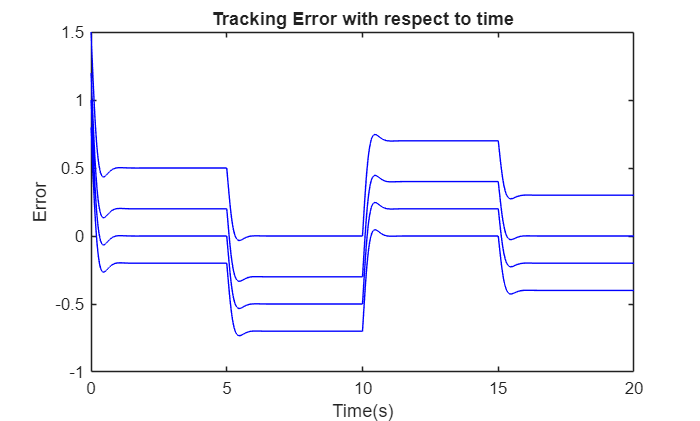

e=r-y;
plot(t,e,'b');
xlabel('Time(s)');
ylabel('Error');
title('Tracking Error with respect to time');

### b)Ramp Input:

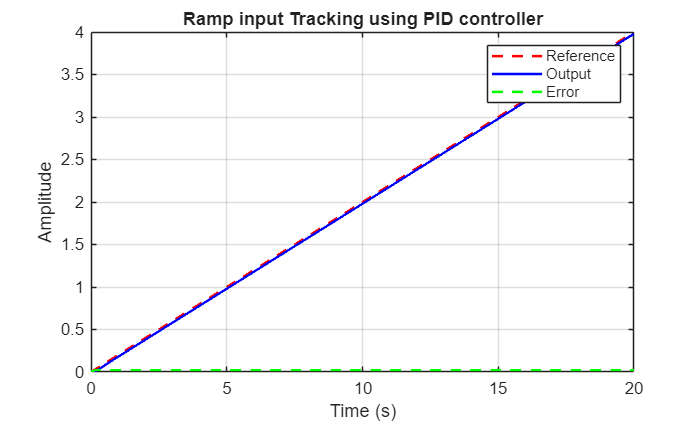

t = 0:0.01:20;
r = 0.2 * t;
[y,t_out]=lsim(T_PID,r,t);
t = t(:);          
r = r(:);
t_out = t_out(:);
y = y(:);
e=r-y;
plot(t,r,'r--',t_out,y,'b',t_out,e,'g--','LineWidth',1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Ramp input Tracking using PID controller');
grid on;
legend('Reference','Output','Error');

ess=e(end);
fprintf('Steady-state error = %4f\n',ess);

Steady-state error = 0.020642


- A ramp input requires a Type-2 system for zero steady-state error.

- PID provides only one integrator → system is typically Type-1.

- Proportional term cannot eliminate continuously growing error.

- Integral term reduces error but cannot fully cancel ramp error alone.

- Derivative term affects transients only, not steady-state error.

### c)Sinosoidal Reference:

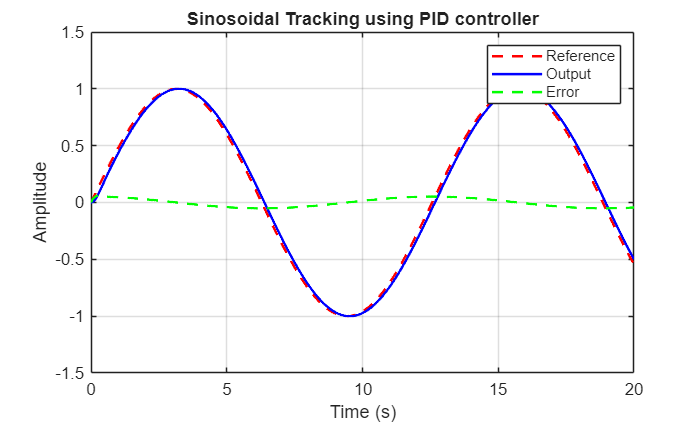

t = 0:0.01:20;
r = sin (0.5 * t);
[y,t_out]=lsim(T_PID,r,t);
t = t(:);          
r = r(:);
t_out = t_out(:);
y = y(:);
e=r-y;
plot(t,r,'r--',t_out,y,'b',t_out,e,'g--','LineWidth',1.5);
xlabel('Time (s)');
ylabel('Amplitude');
title('Sinosoidal Tracking using PID controller');
grid on;
legend('Reference','Output','Error');

- The Derivative Term affects the sinosoidal Tracking the most especially at higher frequencies.

- It Adds phase lead, improving phase alignment between output and sinusoidal reference.

- Helps reduce phase lag and improve waveform matching.

## Problem 3)Practical PID Implementation Challenges

### a)Observing Integral Windup

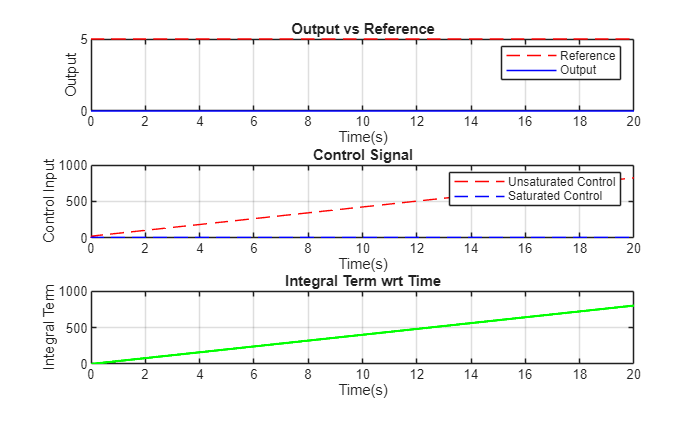

s=tf('s');
G=50/(s^3+8*s^2+25*s+20);
Kp=5;
Ki=8;
C_PI=Kp+Ki/s;
T_PI=feedback(C_PI*G,1);
dt = 0.01;
t = 0: dt :20;
for i=1:length(t)
    r(i)=5;
end
y_a = zeros ( size (t));
u_a = zeros ( size (t));
u_sat_a = zeros ( size (t));
e_int_a = 0;
%e_prev = 0;
for i = 2: length (t)
% Calculate error
e = r(i) - y_a(i -1);
%Integrate error
e_int_a = e_int_a + e * dt;
% PID controller
u_p = Kp * e;
u_i = Ki * e_int_a ;
%u_d = Kd * (e - e_prev ) / dt;
u_a(i) = u_p + u_i ;
u_sat_a(i)=max(min(u_a(i), 10), -10);


% Update plant ( simplified )
% y(i) = ... ( based on plant dynamics )
%e_prev = e;
 [y_step, ~] = lsim(G, [u_sat_a(i-1) u_sat_a(i)], [0 dt], y_a(i-1));

    % Take final value
    y_a(i) = y_step(end);
end

figure;
subplot(3,1,1)
plot(t,r,'r--',t,y_a,'b');
grid on;
xlabel('Time(s)');
ylabel('Output');
legend('Reference','Output');
title('Output vs Reference');

subplot(3,1,2)
plot(t,u_a,'r--',t,u_sat_a,'b--');
grid on;
xlabel('Time(s)');
ylabel('Control Input');
legend('Unsaturated Control','Saturated Control');
title('Control Signal');

subplot(3,1,3)
plot(t,Ki*cumsum(r-y_a)*dt,'g','LineWidth',1.5);
grid on;
xlabel('Time(s)');
ylabel('Integral Term');
title('Integral Term wrt Time');

### b)Implementing Anti-Windup:

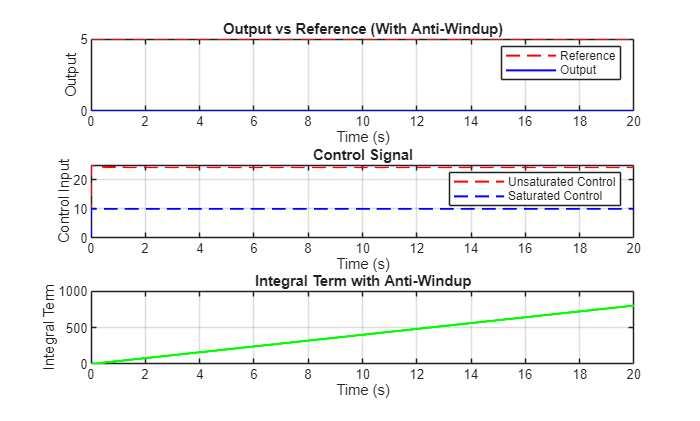


% Plant
s = tf('s');
G = 50/(s^3 + 8*s^2 + 25*s + 20);

% PI gains
Kp = 5;
Ki = 8;
Kt = sqrt(Ki);   % tracking gain for anti-windup

% Simulation parameters
dt = 0.01;
t = 0:dt:20;

% Reference (step = 5)
r = 5*ones(size(t));

% Initialization
y_b = zeros(size(t));
u_b = zeros(size(t));
u_sat_b = zeros(size(t));
e_int_b = 0;

% Simulation loop
for i = 2:length(t)

    % Error
    e = r(i) - y_b(i-1);

    % Unsaturated PI control
    u_p = Kp * e;
    u_i = Ki * e_int_b;
    u_b(i) = u_p + u_i;

    % Actuator saturation
    u_sat_b(i) = max(min(u_b(i), 10), -10);

    % -------- Anti-windup integrator update --------
    e_int_b = e_int_b + dt * ( e + (1/Kt)*(u_sat_b(i) - u_b(i)) );
    % ----------------------------------------------

    % Plant update using lsim
    [y_step, ~] = lsim(G, [u_sat_b(i-1) u_sat_b(i)], [0 dt], y_b(i-1));
    y_b(i) = y_step(end);
end

figure;

subplot(3,1,1)
plot(t, r, 'r--', t, y_b, 'b', 'LineWidth', 1.2)
grid on;
xlabel('Time (s)')
ylabel('Output')
legend('Reference','Output')
title('Output vs Reference (With Anti-Windup)')

subplot(3,1,2)
plot(t, u_b, 'r--', t, u_sat_b, 'b--', 'LineWidth', 1.2)
grid on;
xlabel('Time (s)')
ylabel('Control Input')
legend('Unsaturated Control','Saturated Control')
title('Control Signal')

subplot(3,1,3)
plot(t, Ki*cumsum(r - y_b)*dt, 'g', 'LineWidth', 1.5)
grid on;
xlabel('Time (s)')
ylabel('Integral Term')
title('Integral Term with Anti-Windup')

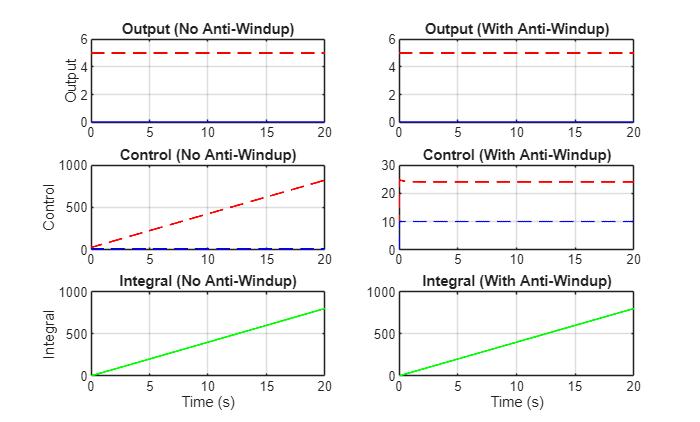

figure;

subplot(3,2,1)
plot(t,r,'r--',t,y_a,'b','LineWidth',1.2)
grid on; title('Output (No Anti-Windup)')
ylabel('Output')

subplot(3,2,2)
plot(t,r,'r--',t,y_b,'b','LineWidth',1.2)
grid on; title('Output (With Anti-Windup)')

subplot(3,2,3)
plot(t,u_a,'r--',t,u_sat_a,'b--','LineWidth',1.2)
grid on; title('Control (No Anti-Windup)')
ylabel('Control')

subplot(3,2,4)
plot(t,u_b,'r--',t,u_sat_b,'b--','LineWidth',1.2)
grid on; title('Control (With Anti-Windup)')

subplot(3,2,5)
plot(t,Ki*cumsum(r-y_a)*dt,'g','LineWidth',1.2)
grid on; title('Integral (No Anti-Windup)')
xlabel('Time (s)')
ylabel('Integral')

subplot(3,2,6)
plot(t,Ki*cumsum(r-y_b)*dt,'g','LineWidth',1.2)
grid on; title('Integral (With Anti-Windup)')
xlabel('Time (s)')

% Reference value
r_final = 5;

% ---------- Maximum Overshoot (%) ----------
OS_noAW = (max(y_a) - r_final)/r_final * 100;
OS_AW   = (max(y_b) - r_final)/r_final * 100;

% ---------- Settling Time (2% criterion) ----------
tol = 0.02 * r_final;

Ts_noAW = t(find(abs(y_a - r_final) <= tol, 1, 'last'));
Ts_AW   = t(find(abs(y_b - r_final) <= tol, 1, 'last'));

% ---------- Time Spent in Saturation ----------
u_max = 10;

satTime_noAW = sum(abs(u_a) > u_max) * dt;
satTime_AW   = sum(abs(u_b) > u_max) * dt;

% ---------- Create Table ----------
ResultsTable = table( ...
    [OS_noAW; OS_AW], ...
    [Ts_noAW; Ts_AW], ...
    [satTime_noAW; satTime_AW], ...
    'VariableNames', {'MaxOvershoot_percent', 'SettlingTime_sec', 'TimeInSaturation_sec'}, ...
    'RowNames', {'Without_AntiWindup', 'With_AntiWindup'} ...
);

% Display table
disp('Quantitative Performance Comparison:')

Quantitative Performance Comparison:


disp(ResultsTable)

                          MaxOvershoot_percent    SettlingTime_sec    TimeInSaturation_sec
                          ____________________    ________________    ____________________

    Without_AntiWindup          -99.998              1×0 double                20         
    With_AntiWindup             -99.998              1×0 double                20         



### c)Derivative Noise and Low-pass Filtering:

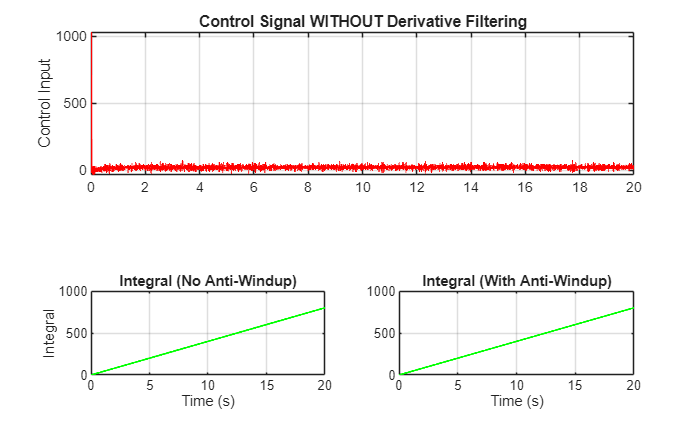


% PID gains
Kp = 5;
Ki = 8;
Kd = 2;
Kt = sqrt(Ki);   % anti-windup gain

% Simulation parameters
dt = 0.01;
t = 0:dt:20;
N = length(t);

% Reference
r = 5*ones(size(t));

%Without Derivative Filtering:
% Initialization
y_nf = zeros(1,N);
u_nf = zeros(1,N);
u_sat_nf = zeros(1,N);

e_int = 0;
e_prev = 0;

for i = 2:N

    % Measurement noise
    y_noisy = y_nf(i-1) + 0.05*randn;

    % Error using noisy measurement
    e = r(i) - y_noisy;

    % Derivative (NO FILTER)
    u_d = Kd*(e - e_prev)/dt;

    % PI terms
    u_p = Kp*e;
    u_i = Ki*e_int;

    % Control
    u = u_p + u_i + u_d;
    u_nf(i) = u;

    % Saturation
    u_sat_nf(i) = max(min(u,10),-10);

    % Anti-windup integrator
    e_int = e_int + dt*( e + (1/Kt)*(u_sat_nf(i) - u) );

    % Plant update
    [y_step,~] = lsim(G,[u_sat_nf(i-1) u_sat_nf(i)],[0 dt],y_nf(i-1));
    y_nf(i) = y_step(end);

    e_prev = e;
end



%With derivative Filtering
% Filter parameters
tau = 0.1;
alpha = tau/(tau + dt);

% Initialization
y_f = zeros(1,N);
u_f = zeros(1,N);
u_sat_f = zeros(1,N);

e_int = 0;
e_prev = 0;
e_filt_prev = 0;

for i = 2:N

    % Measurement noise
    y_noisy = y_f(i-1) + 0.05*randn;

    % Error
    e = r(i) - y_noisy;

    % First-order low-pass filtering of error
    e_filt = alpha*e_filt_prev + (1-alpha)*e;

    % Filtered derivative
    u_d = Kd*(e_filt - e_filt_prev)/dt;

    % PI terms
    u_p = Kp*e;
    u_i = Ki*e_int;

    % Control
    u = u_p + u_i + u_d;
    u_f(i) = u;

    % Saturation
    u_sat_f(i) = max(min(u,10),-10);

    % Anti-windup integrator
    e_int = e_int + dt*( e + (1/Kt)*(u_sat_f(i) - u) );

    % Plant update
    [y_step,~] = lsim(G,[u_sat_f(i-1) u_sat_f(i)],[0 dt],y_f(i-1));
    y_f(i) = y_step(end);

    % Update memory
    e_prev = e;
    e_filt_prev = e_filt;
end
subplot(2,1,1)
plot(t,u_nf,'r','LineWidth',1)
grid on;
title('Control Signal WITHOUT Derivative Filtering')
ylabel('Control Input')

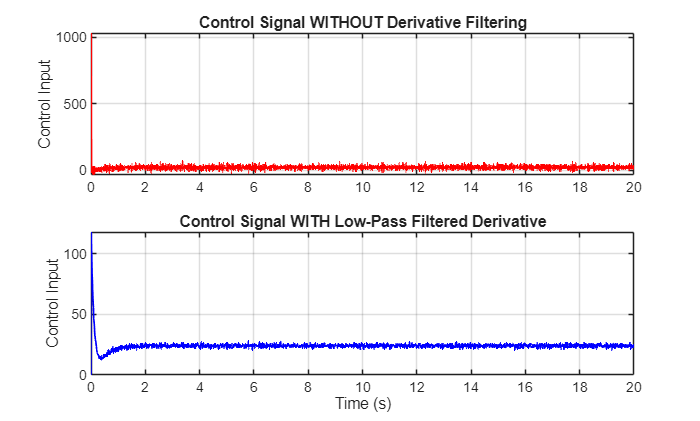


subplot(2,1,2)
plot(t,u_f,'b','LineWidth',1)
grid on;
title('Control Signal WITH Low-Pass Filtered Derivative')
xlabel('Time (s)')
ylabel('Control Input')

### d)Complex Trajectory tracking:

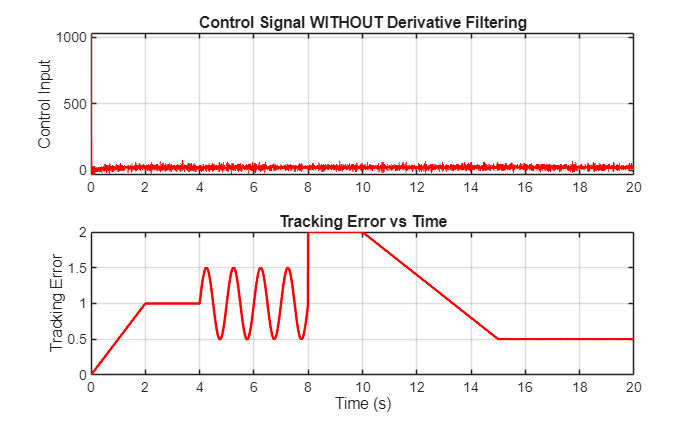

r = zeros(size(t));

for i = 1:N
    if t(i) < 2
        r(i) = 0.5*t(i);                      % ramp up
    elseif t(i) < 4
        r(i) = 1;                             % hold
    elseif t(i) < 8
        r(i) = 1 + 0.5*sin(2*pi*(t(i)-4));    % oscillation
    elseif t(i) < 10
        r(i) = 2;                             % step up
    elseif t(i) < 15
        r(i) = 2 - 0.3*(t(i)-10);             % ramp down
    else
        r(i) = 0.5;                           % final hold
    end
end
% Filter parameters
tau = 0.1;
alpha = tau/(tau + dt);

% Initialization
y = zeros(1,N);
u = zeros(1,N);
u_sat = zeros(1,N);

e_int = 0;
e_filt_prev = 0;

for i = 2:N

    % Error
    e = r(i) - y(i-1);

    % Low-pass filtered derivative of error
    e_filt = alpha*e_filt_prev + (1-alpha)*e;
    u_d = Kd*(e_filt - e_filt_prev)/dt;

    % PI terms
    u_p = Kp*e;
    u_i = Ki*e_int;

    % Control signal
    u(i) = u_p + u_i + u_d;

    % Saturation
    u_sat(i) = max(min(u(i), 10), -10);

    % Anti-windup integrator update
    e_int = e_int + dt*( e + (1/Kt)*(u_sat(i) - u(i)) );

    % Plant update
    [y_step,~] = lsim(G,[u_sat(i-1) u_sat(i)],[0 dt],y(i-1));
    y(i) = y_step(end);

    % Update memory
    e_filt_prev = e_filt;
end
%)Plotting the graphs
plot(t,r,'r--',t,y,'b','LineWidth',1.5)
grid on;
xlabel('Time (s)')
ylabel('Output')
legend('Reference','Output')
title('Complex Trajectory Tracking')


%)Plotting tracking error
plot(t,r-y,'r','LineWidth',1.5)
grid on;
xlabel('Time (s)')
ylabel('Tracking Error')
title('Tracking Error vs Time')

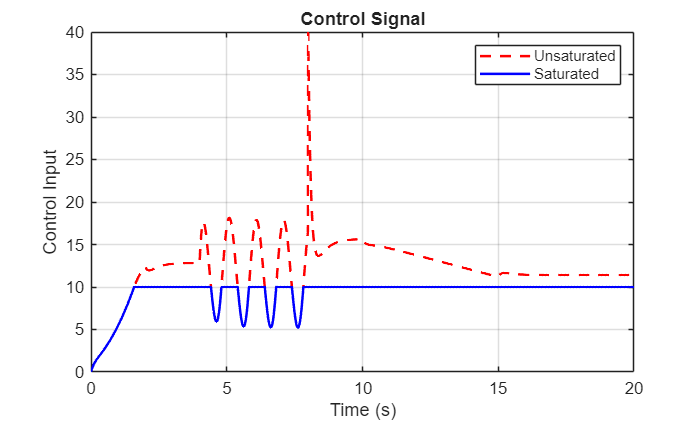


%)Control Signal
figure;
plot(t,u,'r--',t,u_sat,'b','LineWidth',1.5)
grid on;
xlabel('Time (s)')
ylabel('Control Input')
legend('Unsaturated','Saturated')
title('Control Signal')


e = r - y;
e_rms = sqrt(mean(e.^2));

fprintf('RMS Tracking Error = %.4f\n', e_rms);

RMS Tracking Error = 1.1218
